# OptForce GAMS

## Author: Sebastián N. Mendoza,  Center for Mathematical Modeling, University of Chile. snmendoz@uc.cl

## **Reviewers(s): Chiam Yu Ng (Costas D. Maranas group), **Lin Wang **(Costas D. Maranas group)**

## **INTRODUCTION:**

In this tutorial we will run optForce. For a detailed description of the procedure, please see [1]. Briefly, the problem is to find a set of interventions of size "K" such that when these interventions are applied to a wild-type strain, the mutant created will produce a particular target of interest in a higher rate than the wild-type strain. The interventions could be knockouts (lead to zero the flux for a particular reaction), upregulations (increase the flux for a particular reaction) and downregulations (decrease the flux for a particular reaction). 

For example, imagine that we would like to increase the production of succinate in Escherichia coli. Which are the interventions needed to increase the production of succinate? We will approach this problem in this tutorial and we will see how each of the steps of OptForce are solved. 

## MATERIALS

## EQUIPMENT

- MATLAB

- GAMS

- A solver for Mixed Integer Linear Programming (MILP) problems. For example, Gurobi.

## **EQUIPMENT SETUP**

**GAMS**: Install the latest version of GAMS available. This is important as some GAMS functions are not supported in versions older than  24.7.1. During GAMS installation make sure to select the option "Add GAMS directory to PATH environment variable". In MATLAB, use functions addpath() and savepath() for adding and saving the directory where GAMS was installed. For a more detailed description of GAMS installation and setup, you can watch the official tutorial of GDXMRW at https://www.youtube.com/watch?v=HPn_q8nlktE

## PROCEDURE

The proceduce consists on the following steps

1) Maximize specific growth rate and product formation.

2) Define constraints for both wild-type and mutant strain: 

3) Perform flux variability analysis for both wild-type and mutant strain.

4) Find must sets,  i.e, reactions that MUST increase or decrease their flux in order to achieve the phenotype in the mutant strain. 

## Figure 1.

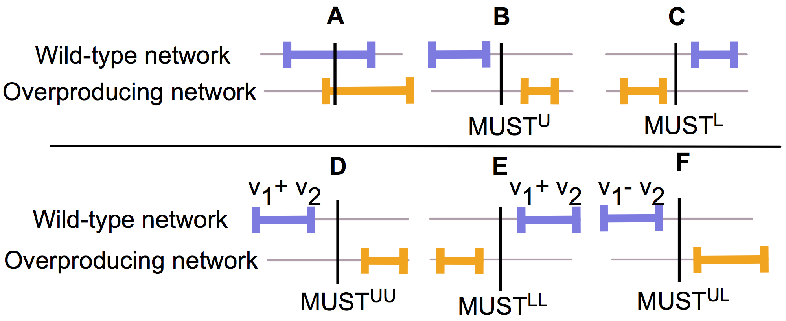

5) Find the interventions needed that will ensure a increased production of the target of interest

Now, we will approach each step in detail.

## STEP 1: Maximize specific growth rate and product formation

First, we load the model. This model comprises only 90 reactions, which describe the central metabolism of E. coli [2].

Then, we change the objective function to maximize biomass ("R75"). We also change the lower bounds, so E. coli will be able to consume glucose, oxygen, sulfate, ammomium, citrate and glycerol.

global TUTORIAL_INIT_CB;
if ~isempty(TUTORIAL_INIT_CB) && TUTORIAL_INIT_CB==1
    initCobraToolbox
    changeCobraSolver('gurobi','all');
end

pathTutorial = which('tutorial_OptForceGAMS.mlx');
pathstr = fileparts(pathTutorial);
cd(pathstr)

modelFileName = 'AntCore.mat';
modelDirectory = getDistributedModelFolder(modelFileName); %Look up the folder for the distributed Models.
modelFileName= [modelDirectory filesep modelFileName]; % Get the full path. Necessary to be sure, that the right model is loaded
model = readCbModel(modelFileName);

model.c(strcmp(model.rxns,'R75')) = 1;
model = changeRxnBounds(model, 'EX_gluc', -100, 'l'); 
model = changeRxnBounds(model, 'EX_o2', -100, 'l'); 
model = changeRxnBounds(model, 'EX_so4', -100, 'l'); 
model = changeRxnBounds(model, 'EX_nh3', -100, 'l'); 
model = changeRxnBounds(model, 'EX_cit', -100, 'l'); 
model = changeRxnBounds(model, 'EX_glyc', -100, 'l'); 

Then, we calculate the maximum specific growth rate and the maximum production rate for succinate

growthRate = optimizeCbModel(model); 
fprintf('The maximum growth rate is %1.2f', growthRate.f);

The maximum growth rate is 14.36


model = changeObjective(model, 'EX_suc');
maxSucc = optimizeCbModel(model);
fprintf('The maximum production rate of succinate is %1.2f', maxSucc.f);

The maximum production rate of succinate is 155.56

**TIP: **The biomass reaction is usually set to 1%-10% of maximum theoretical biomass yield when running the following steps, to prevent solutions with not biomass formation

- maximizing product formation

- finding MUST sets of second order

- finding FORCE sets

## STEP 2: Define constraints for both wild-type and mutant strain

**TIMING**: This step should take a few days or weeks, depending on the information available for your species. 

**CRITICAL STEP**: This is a manual task, so you should search for information in articles or even perform your own experiments. You can also make assumptions for describing the phenotypes of both strains which will make this task a little faster but make sure to have two strains different enough, because you should be able to find differences in reactions ranges. 

First, we load the model. This model comprises only 90 reactions, which describe the central metabolism of E. coli [2].

Then, we change the objective function to maximize biomass ("R75"). We also change the lower bounds, so E. coli will be able to consume glucose, oxygen, sulfate, ammomium, citrate and glycerol. 

We define constraints for each strain

Constr_WT = struct('rxnList', {{'R75'}}, 'rxnValues', 14, 'rxnBoundType', 'b');
Constr_MT = struct('rxnList', {{'R75','EX_suc'}}, 'rxnValues', [0, 155.55], 'rxnBoundType', 'bb');

## Step 3: Flux Variability Analysis

**TIMING**: This task should take from a few seconds to a few hours depending on the size of your reconstruction

We  run the FVA analysis for both strains

[minFluxes_WT, maxFluxes_WT, minFluxes_MT, maxFluxes_MT,~,~] = FVAOptForce(model, Constr_WT, Constr_MT);
disp([minFluxes_WT, maxFluxes_WT, minFluxes_MT, maxFluxes_MT]);

  -90.1251   97.1300   44.4313  100.0000
         0   86.0700   44.4375  100.0000
         0   86.0700   44.4375  100.0000
  -56.1567   86.0700  -44.4500   11.1143
   21.3033  163.5300   55.5500  111.1143
   -3.0777  154.8640   55.5500  111.1143
         0  151.5086         0   55.5625
         0  187.2551         0   55.5687
         0  169.5163         0    0.0187
  -10.0660  102.9449         0    0.0125
   10.0660   66.5714         0    0.0063
  -10.0660  102.9449         0    0.0125
  -48.9454    7.5600   -0.0063         0
  -53.9994    2.5060   -0.0063         0
  -53.9994    2.5060   -0.0063         0
   -2.5060   53.9994         0    0.0063
         0   86.0700         0   55.5625
         0   86.0700         0   55.5625
    9.7020  114.6466   55.5500   55.5625
         0   56.5564   55.5500   55.5571
   16.0264  145.2048  155.5500  155.5563
   16.0264  145.2048  155.5500  155.5563
    0.9344  130.1128  155.5500  155.5562
   -5.6736  123.5048  155.5500  155.5563
         0  118.

Now, the run the second step of OptForce.

## Step 4: Find Must Sets

**TIMING: **This task should take from a few seconds to a few hours depending on the size of your reconstruction

First, we define an ID for this run. Each time you run the functions associated to the optForce procedure, some folders can be generated to store inputs used in that run. Outputs are stored as well. These folder will be located inside the folder defined by your run ID. Thus, if your runID is ''TestOptForce", the structure of the folders will be the following:

`├── CurrentFolder`

`|   ├── TestOptForce`

`|   |   ├── Inputs`

`|   |   └── Outputs`

To avoid the generation of inputs and outputs folders, set keepInputs = 0, printExcel = 0, printText = 0 and keepGamsOutputs = 0

Also, a report of the run is generated each time you run the functions associated to the optForce procedure. So, the idea is to give a different runID each time you run the functions, so you will be able to see the report (inputs used, outputs generated, errors in the run) for each run.

We define then our runID

runID = 'TestOptForce';

Fow now, only functions to find first and second order must sets are supported. As depicted in **Figure 1**, the first order must sets are MUSTU and MUSTL; and second order must sets are MUSTUU, MUSTLL and MUSTUL

**A) Finding first order must sets**

We define constraints

constrOpt = struct('rxnList', {{'EX_gluc','R75','EX_suc'}}, 'values', [-100, 0, 155.5]');

We then run the functions findMustLWithGAMS.m and findMustUWithGAMS.m that will find mustU and mustL sets, respectively.

Important: To run these function you will need a solver able to solve Mixed Integer Linear Programming (MILP or MIP) problems. Some popular options are: cplex and gurobi. You can see which gams solvers are available in your systems to solve MIP problems by running checkGAMSSolvers('MIP')

solvers = checkGAMSSolvers('MIP'); disp(solvers);

  Columns 1 through 12

    'AMPL'    'BARON'    'BDMLP'    'BENCH'    'CBC'    'CONVERT'    'CPLEX'    'EXAMINER'    'GAMSCHK'    'GUROBI'    'KESTREL'    'LINDO'

  Columns 13 through 22

    'LINDOGLOBAL'    'LINGO'    'LOCALSOLVER'    'MOSEK'    'MPECDUMP'    'OsiCplex'    'OsiGurobi'    'OsiMosek'    'OsiXpress'    'PYOMO'

  Columns 23 through 25

    'SCIP'    'XA'    'XPRESS'



We then run findMustLWithGAMS.m and findMustUWithGAMS.m. 

**i) MustL Set: **

[mustLSet, pos_mustL] = findMustLWithGAMS(model, minFluxes_WT, maxFluxes_WT, 'constrOpt', constrOpt, ...
'solverName', 'cplex', 'runID', runID, 'outputFolder', 'OutputsFindMustL', 'outputFileName', 'MustL', ...
'printExcel', 1, 'printText', 1, 'printReport', 1, 'keepInputs', 1, 'keepGamsOutputs', 1, 'verbose', 0);

Note that the folder "TestOptForce" was created. Inside this folder, two additional folders were created: "InputsMustL" and "OutputsFindMustL". In the inputs folder you will find all the inputs required to run the GAMS function "findMustL.gms". Additionally, in the outputs folder you will find the mustL set found, which were saved in two files (.xls and .txt), as well as other files generated automatically by GAMS. Furthermore, a report which summarize all the inputs and outputs used during your running was generated. The name of the report will be in this format "report-Day-Month-Year-Hour-Minutes". So, you can mantain a chronological order of your experiments

We display the reactions that belongs to the mustL set

disp(mustLSet)

    'R11'
    'R26'
    'R37'
    'R38'
    'R39'
    'R40'
    'R41'
    'R42'
    'R43'
    'R46'
    'R48'
    'R49'
    'R50'
    'R51'
    'R52'
    'R53'
    'R54'
    'R55'
    'R56'
    'R57'
    'R58'
    'R59'
    'R60'
    'R61'
    'R73'
    'R74'
    'PSEUDOpyr_1'
    'PSEUDOpep_1'
    'PSEUDOco2_1'



**ii) MustU set: **

[mustUSet, pos_mustU] = findMustUWithGAMS(model, minFluxes_WT, maxFluxes_WT, 'constrOpt', constrOpt, ...
'solverName', 'cplex', 'runID', runID, 'outputFolder', 'OutputsFindMustU', 'outputFileName', 'MustU', ...
'printExcel', 1, 'printText', 1, 'printReport', 1, 'keepInputs', 1, 'keepGamsOutputs', 1, 'verbose', 0);

Note that the folders "InputsMustU" and "OutputsFindMustU" were created. These folders contain the inputs and outputs of findMustUWithGAMS.m, respectively. 

We display the reactions that belongs to the mustU set

disp(mustUSet)

    'R21'
    'R22'
    'R23'
    'R24'
    'R33'
    'R34'
    'R35'
    'R36'
    'R69'
    'EX_pdo'
    'EX_nh3'
    'EX_so4'
    'SUCt'



**B) Finding second order must sets **

First, we define the reactions that will be excluded from the analysis. It it suggested to eliminate reactions found in the previous step as well as exchange reactions

constrOpt = struct('rxnList', {{'EX_gluc','R75','EX_suc'}}, 'values', [-100, 0, 155.5]');
exchangeRxns = model.rxns(cellfun(@isempty, strfind(model.rxns, 'EX_')) == 0);
excludedRxns = unique([mustUSet; mustLSet; exchangeRxns]);
mustSetFirstOrder = unique([mustUSet; mustLSet]);

Now, we run the functions for finding second order must sets

**i) MustUU: **

[mustUU, pos_mustUU, mustUU_linear, pos_mustUU_linear] = findMustUUWithGAMS(model, minFluxes_WT, maxFluxes_WT, ...
     'constrOpt', constrOpt, 'excludedRxns', excludedRxns, 'mustSetFirstOrder', mustSetFirstOrder, 'solverName', 'cplex',...
    'runID', runID, 'outputFolder', 'OutputsFindMustUU', 'outputFileName', 'MustUU' , 'printExcel', 1, 'printText', 1, ...
    'printReport', 1, 'keepInputs', 1, 'keepGamsOutputs', 1, 'verbose', 0);

Note that the folders "InputsMustUU" and "OutputsFindMustUU" were created. These folders contain the inputs and outputs of findMustUUWithGAMS.m, respectively. 

We display the reactions that belongs to the mustUU set

disp(mustUU);

    'R30'    'R65'
    'R65'    'R31'



**ii) MustLL: **

[mustLL, pos_mustLL, mustLL_linear, pos_mustLL_linear] = findMustLLWithGAMS(model, minFluxes_WT, maxFluxes_WT, ...
     'constrOpt', constrOpt, 'excludedRxns', excludedRxns, 'mustSetFirstOrder', mustSetFirstOrder, 'solverName', 'cplex',...
    'runID', runID, 'outputFolder', 'OutputsFindMustLL', 'outputFileName', 'MustLL' , 'printExcel', 1, 'printText', 1, ...
    'printReport', 1, 'keepInputs', 1, 'keepGamsOutputs', 1, 'verbose', 0);

Note that the folders "InputsMustLL" and "OutputsFindMustLL" were created. These folders contain the inputs and outputs of findMustLLWithGAMS.m, respectively. 

We display the reactions that belongs to the mustLL set. In this case, MustLL is an empty array because no reaction was found in the mustLL set.

disp(mustLL);

**iii) MustUL: **

[mustUL, pos_mustUL, mustUL_linear, pos_mustUL_linear] = findMustULWithGAMS(model, minFluxes_WT, maxFluxes_WT, ...
     'constrOpt', constrOpt, 'excludedRxns', excludedRxns, 'mustSetFirstOrder', mustSetFirstOrder, 'solverName', 'cplex',...
    'runID', runID, 'outputFolder', 'OutputsFindMustUL', 'outputFileName', 'MustUL' , 'printExcel', 1, 'printText', 1, ...
    'printReport', 1, 'keepInputs', 1, 'keepGamsOutputs', 1, 'verbose', 0);

Note that the folders "InputsMustUL" and "OutputsFindMustUL" were created. These folders contain the inputs and outputs of findMustULWithGAMS.m, respectively. 

We display the reactions that belongs to the mustUL set. In this case, MustUL is an empty array because no reaction was found in the mustUL set.

disp(mustUL);

**TROUBLESHOOTING 1: ** "I didn't find any reaction in my must sets"

**TROUBLESHOOTING 2: ** "I got an error when running the findMustXWithGAMS.m functions (X = L or U or LL or UL or UU depending on the case)"

## Step 5: OptForce

**TIMING: **This task should take from a few seconds to a few hours depending on the size of your reconstruction

We define constraints and we define "K" the number of interventions allowed, "nSets" the maximum number of sets to find, and "targetRxn" the reaction producing the metabolite of interest (in this case, succinate). 

Additionally, we define the mustU set as the union of the reactions that must be upregulated in both first and second order must sets; and mustL set as the union of the reactions that must be downregulated in both first and second order must sets 

mustU = unique(union(mustUSet, mustUU));
mustL = unique(union(mustLSet, mustLL));
targetRxn = 'EX_suc';
k = 1;
nSets = 1;
constrOpt = struct('rxnList', {{'EX_gluc','R75'}}, 'values', [-100, 0]);

[optForceSets, posOptForceSets, typeRegOptForceSets] = optForceWithGAMS(model, targetRxn, mustU, mustL, minFluxes_WT, ...
    maxFluxes_WT, minFluxes_MT, maxFluxes_MT, 'k', k, 'nSets', nSets, 'constrOpt', constrOpt, ...
    'runID', runID, 'outputFolder', 'OutputsOptForce', 'outputFileName', 'OptForce', 'solverName', 'cplex', 'printExcel', 1, 'printText', 1, ...
    'printReport', 1, 'keepInputs', 1, 'keepGamsOutputs', 1,'verbose', 0);

Note that the folders "InputsOptForce" and "OutputsOptForce" were created. These folders contain the inputs and outputs of optForceWithGAMS.m, respectively.

We display the reactions found by optForce

disp(optForceSets)

    'SUCt'



The reaction found was "SUCt", i.e. a transporter for succinate (a very intuitive solution).

Next, we will increase "k" and we will exclude "SUCt" from upregulations to found non-intuitive solutions. 

**TIP: **Sometimes the product is at the end of a long linear pathway. In that case, the recomendation is to also exclude most reactions on the linear pathway. Essential reactions and reactions not associated with any gene should also be excluded. 

We will only search for the 20 best solutions, but you can try with a higher number.

We will change the runID to save both resutls (k = 1 and K = 2) in diffetent folders

k = 2;
nSets = 20;
runID = 'TestOptForce2';
excludedRxns = struct('rxnList', {{'SUCt'}}, 'typeReg','U');
[optForceSets, posOptForceSets, typeRegOptForceSets] = optForceWithGAMS(model, targetRxn, mustU, mustL, minFluxes_WT, ...
    maxFluxes_WT, minFluxes_MT, maxFluxes_MT, 'k', k, 'nSets', nSets, 'constrOpt', constrOpt, 'excludedRxns', excludedRxns, ...
    'runID', runID, 'outputFolder', 'OutputsOptForce', 'outputFileName', 'OptForce', 'solverName', 'cplex', 'printExcel', 1, 'printText', 1, ...
    'printReport', 1, 'keepInputs', 1, 'keepGamsOutputs', 1,'verbose', 0);

Note that the folders "InputsOptForce" and "OutputsOptForce" were created inside TestOptForce2. These folders contain the inputs and outputs of optForceWithGAMS.m, respectively.

We display the reactions found by optForce

disp(optForceSets)

    'R23'    'R26'
    'R24'    'R25'
    'R24'    'R26'
    'R23'    'R25'
    'R23'    'R26'
    'R23'    'R63'
    'R22'    'R25'
    'R24'    'R63'
    'R21'    'R26'
    'R24'    'R26'
    'R22'    'R26'
    'R22'    'R63'
    'R22'    'R26'
    'R21'    'R63'
    'R21'    'R25'
    'R21'    'R26'
    'R24'    'R4' 
    'R23'    'R4' 
    'R22'    'R4' 
    'R21'    'R4' 



## TIMING

- STEP 1: < 1 second

- STEP 2: ~ 1-2 seconds

- STEP 3:  ~ 2-5 seconds

- STEP 4: ~ 10-20 seconds

- STEP 5: ~ 10-20 seconds

## TROUBLESHOOTING

1) problem: "I didn't find any reaction in my must sets"

possible reason: the wild-type or mutant strain is not constrained enough. 

solution: add more constraints to your strains until you find differences in your reaction ranges. If you don't find any differences, it is better to change the approach and use another algorithm. Also, it is possible that you won't find second order must set (like in this tutorial). You can check if the algorithm is working by defining excludedRxns as an empty array. If the algorihm is working well, you should see how the must sets are found in each iteration.

2) problem: "I got an error when running the findMust functions"

possible reason: inputs are not defined well or GAMS was not installed correctly

solution: verify your inputs. To verify that GAMS was installed correctly, in MATLAB, use the function which('gams'). If a folder is shown, GAMS was installed correctly.

## ANTICIPATED RESULTS

In this tutorial some folders will be created inside the folder called "runID" to store inputs and outputs of the optForce functions (findMustUWithGams.m, findMustLWithGams.m, findMustUUWithGams.m, findMustLLWithGams.m, findMustULWithGams.m, optForceWithGams.m)

In this case runID = 'TestOptForce', so inside this folder the following folders will be created:

`├── CurrentFolder`

`|   ├── TestOptForce`

`|   |   ├── InputsFindMustL`

`|   |   ├── OutputsFindMustL`

`|   |   ├── InputsFindMustU`

`|   |   ├── OutputsFindMustU`

`|   |   ├── InputsFindMustLL`

`|   |   ├── OutputsFindMustLL`

`|   |   ├── InputsFindMustUU`

`|   |   ├── OutputsFindMustUU`

`|   |   ├── InputsFindMustUL`

`|   |   ├── OutputsFindMustUL`

`|   |   ├── InputsOptForce`

`|   |   └── OutputsOptForce`

The input folders contain inputs (.txt and .gdx files) for running the GAMS functions to solve each one of the bilevel problems. Output folders contain results of the algorithms (.xls and .txt files) as well as a report (.txt) summarizing the outcomes of the steps performed during the execution of the optForce functions. Additionally, some auto-generated files will be stored (.gdx and .lst files). These files are generated by GAMS automatically and contain values for variables and the summary of the GAMS execution, respectively.

The optForce algorithm will find sets of reactions that should increase the production of your target. The first sets found should be the best ones because the production rate will be the highest. The last ones should be the worse because the production rete will be slower. Be aware that some sets could not guarante a minimum production rate for your target, so you always have to check the minimum production rate. You can do this using the function testOptForceSol.m. Some sets could allow a higher growth rate than others, so keep in mind this too when deciding which set is better.

## Acknowledgments

I would to thanks to the research group of Costas D. Maranas who provided the GAMS functions to solve this example. In particular I would like to thank to Chiam Yu Ng who kindly provided examples for using GAMS and support for writing GAMS functions.

## References

[1] Ranganathan S, Suthers PF, Maranas CD (2010) OptForce: An Optimization Procedure for Identifying All Genetic Manipulations Leading to Targeted Overproductions. PLOS Computational Biology 6(4): e1000744. https://doi.org/10.1371/journal.pcbi.1000744.

[2] Maciek R. Antoniewicz, David F. Kraynie, Lisa A. Laffend, Joanna González-Lergier, Joanne K. Kelleher, Gregory Stephanopoulos, Metabolic flux analysis in a nonstationary system: Fed-batch fermentation of a high yielding strain of E. coli producing 1,3-propanediol, Metabolic Engineering, Volume 9, Issue 3, May 2007, Pages 277-292, ISSN 1096-7176, https://doi.org/10.1016/j.ymben.2007.01.003.